# Training script for a DQN agent

clc;
clear all;
close all;


### Initial parameters

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('code');
Parameters; % Script containing necessary variables 

Error using Parameters>addingPathParentFolderByName (line 149)
Folder named "COMSOL_Three_Pipes" not found in any parent directory.

Error in Parameters (line 3)
addingPathParentFolderByName('COMSOL_Three_Pipes');
^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

#### Environment: 2DFT as evaluated by the SIM 1 physics

Description: The environment is defined with the cell EnvPars

EnvPars.N = evalin('base','N');
EnvPars.N_x = evalin('base','N_x');
EnvPars.N_y = evalin('base','N_y');
EnvPars.T = evalin('base','T');
EnvPars.T_x = evalin('base','T_x');
EnvPars.T_y = evalin('base','T_y');
EnvPars.SNR_dB = evalin('base','SNR_dB');
EnvPars.theta_min = evalin('base','theta_min');
EnvPars.theta_max = evalin('base','theta_max');

% Meta-atom indexing
n = (1:EnvPars.N);
n_y = ceil(n ./ EnvPars.N_x);
n_x = n - (n_y - 1) .* EnvPars.N_x;

% Psi indexing
n_psi = n;
n_psi_y = ceil(n_psi ./ EnvPars.N_x);
n_psi_x = n_psi - (n_y - 1) .* EnvPars.N_x;

% Kernel 2D-DFT 
G_func = @(n,n_psi) exp(-1i*2*pi*(n_psi_x(n_psi)-1)/EnvPars.N_x.*(n_x(n)-1)).* ...
    exp(-1i*2*pi*(n_psi_y(n_psi)-1)/EnvPars.N_y.*(n_y(n)-1));
[n_psi_grid, n_s_grid] = ndgrid(1:EnvPars.N, 1:EnvPars.N);
EnvPars.G = G_func(n_s_grid, n_psi_grid);

% Snapshots indexing
t = (1:EnvPars.T);
EnvPars.t_y = ceil(t ./ EnvPars.T_x);
EnvPars.t_x = t - (EnvPars.t_y - 1) .* EnvPars.T_x;


#### Agent parameters

Description: The agent observations and actions are mapped to SIM 1.


% Actions given by the Upsilon coefficient
EnvPars.U_func = @(n_, t_n_) exp(1i * ( ...
    -2*pi*(n_x(n_)-1) * (EnvPars.t_x(t_n_)-1) / (EnvPars.N_x*EnvPars.T_x) ...
    -2*pi*(n_y(n_)-1) * (EnvPars.t_y(t_n_)-1) / (EnvPars.N_y*EnvPars.T_y) ));

% Episode parameters (will be initialized on reset)
EnvPars.psi_x = 0;
EnvPars.psi_y = 0;
EnvPars.maxSteps = EnvPars.T;
EnvPars.tolerance = pi/80; % error tolerance

% Definition of Observations and Actions
ObsInfo = rlNumericSpec([4 1]);
ObsInfo.Name = 'observations';
ObsInfo.Description = 'psi_x_est, psi_y_est, error_x, error_y';

ActInfo = rlFiniteSetSpec(1:EnvPars.T);
ActInfo.Name = 'actions';
ActInfo.Description = 'phase snapshot index t_psi';

% Create the environment
StepHandle = @(Action, LoggedSignals) stepFunction(Action, LoggedSignals, EnvPars);
ResetHandle = @() resetFunction(EnvPars);
env = rlFunctionEnv(ObsInfo, ActInfo, StepHandle, ResetHandle);


### Step function

function [NextObs, Reward, IsDone, LoggedSignals] = stepFunction(Action, LoggedSignals, EnvPars)
    
    % Unpack the state of the LoggedSignals struct
    stepCount = LoggedSignals.stepCount;
    psi_x_true = LoggedSignals.psi_x_true;
    psi_y_true = LoggedSignals.psi_y_true;
    prev_error_sum = LoggedSignals.error_sum;

    % Apply action
    t_psi = double(Action);
    stepCount = stepCount + 1;

    % Build the true steering vector
    a_psi_x = exp(1i * psi_x_true * ((1:EnvPars.N_x) - 1))';
    a_psi_y = exp(1i * psi_y_true * ((1:EnvPars.N_y) - 1))';
    a_psi_x_y = kron(a_psi_y, a_psi_x);

    % Create Upsilon and G*Upsilon
    v0 = EnvPars.U_func(1:EnvPars.N, t_psi);
    Upsilon = diag(v0');
    G_Upsilon = EnvPars.G * Upsilon;

    % Evaluate the received signal 'r' with noise
    s = 1;
    u = (randn(EnvPars.N,1) + 1i*randn(EnvPars.N,1)) / sqrt(2);
    r = sqrt(db2pow(EnvPars.SNR_dB)) * G_Upsilon * a_psi_x_y * s + u;

    % Find the maximum of 2D-DFT and its indices
    R = flipud(fliplr(reshape(abs(r), [EnvPars.N_x, EnvPars.N_y])))';
    [~, linear_idx] = max(R, [], 'all');
    % [n_psi_y_max, n_psi_x_max] = ind2sub(size(R), linear_idx);
    n_psi_x_max = ceil(linear_idx/EnvPars.N_x);
    n_psi_y_max = linear_idx-(n_psi_x_max-1)*EnvPars.N_x;

    % Obtain temporal coordinates of displacement t_psi
    t_psi_x_max = EnvPars.t_x(t_psi);
    t_psi_y_max = EnvPars.t_y(t_psi);

    % Estimate electrical angles
    psi_x_est = mod(2*pi * (n_psi_x_max + (t_psi_x_max) / EnvPars.T_x) / EnvPars.N_x, 2*pi);
    psi_y_est = mod(2*pi * (n_psi_y_max + (t_psi_y_max) / EnvPars.T_y) / EnvPars.N_y, 2*pi);

    % Evaluate absolute errors
    error_x = abs(psi_x_true - psi_x_est);
    error_y = abs(psi_y_true - psi_y_est);
    
    % Relative errors
    % error_x_relative = abs(psi_x_true-psi_x_est)/abs(psi_x_true)*100;
    % error_y_relative = abs(psi_y_true-psi_y_est)/abs(psi_y_true)*100;
    error_sum = 0.5*(error_x + error_y); % max(x,y), mean(x,y)

    % Reward function
    % Parameters (tune as needed)
    eps_norm       = 1e-6;   % avoid division by zero
    quality_scale  = 10;     % continuous per-step scale
    improve_scale  = 5;      % improvement kick scale
    lambda_pen     = 0.05;   % small penalty when far from target
    success_bonus  = 10;     % modest terminal bonus
    tolerance      = EnvPars.tolerance;

    % Continuous quality: positive and smooth near zero error
    quality = quality_scale/(1 + error_sum);        % ~[0, quality_scale]
    
    % Normalized improvement: bounded and centered
    norm_improv = (prev_error_sum - error_sum)/(eps_norm + prev_error_sum);  % in (-∞,1], ~[-1,1]
    improvement = improve_scale * norm_improv;       % ~[-improve_scale, +improve_scale]
    
    % Conditional time penalty only when not in the good band
    time_penalty = (error_sum > tolerance) * (-lambda_pen);
    
    % Terminal bonus (one-time at success)
    terminal_bonus = (error_sum < tolerance) * success_bonus;
    
    % Zero-centered final reward, clipped to stable range
    Reward = (quality + improvement + time_penalty + terminal_bonus) - (quality_scale/2);
    Reward = max(-10, min(20, Reward));

    % Term condition
    IsDone = (error_sum < EnvPars.tolerance) || (stepCount >= EnvPars.maxSteps);

    % Pack state and observations for the next step
    LoggedSignals.stepCount = stepCount;
    LoggedSignals.psi_x_est = psi_x_est;
    LoggedSignals.psi_y_est = psi_y_est;
    LoggedSignals.error_sum = error_sum;
    
    NextObs = [psi_x_est; psi_y_est; error_x; error_y];
end


### Reset function

function [InitialObs, LoggedSignals] = resetFunction(EnvPars)
    
    % Random true angles for each episode
    psi_x_true = (EnvPars.theta_max - EnvPars.theta_min) * rand() + EnvPars.theta_min;
    psi_y_true = (EnvPars.theta_max - EnvPars.theta_min) * rand() + EnvPars.theta_min;
    % psi_x_true = 3*pi/4;%deterministic x-component for the electric angle
    % psi_y_true = pi/2;%deterministic x-component for the electric angle

    % Build the true steering vector
    a_psi_x = exp(1i * psi_x_true * ((1:EnvPars.N_x) - 1))';
    a_psi_y = exp(1i * psi_y_true * ((1:EnvPars.N_y) - 1))';
    a_psi_x_y = kron(a_psi_y, a_psi_x);

    % Initial measurement with t_psi = 1
    t_psi = 1; % randi
    v0 = EnvPars.U_func(1:EnvPars.N, t_psi);
    Upsilon = diag(v0');
    G_Upsilon = EnvPars.G * Upsilon;

    % Evaluate the received signal 'r' with noise
    s = 1;
    u = (randn(EnvPars.N,1) + 1i*randn(EnvPars.N,1)) / sqrt(2);
    r = sqrt(db2pow(EnvPars.SNR_dB)) * G_Upsilon * a_psi_x_y * s + u;

    % Find the maximum of 2D-DFT and its indices
    R = flipud(fliplr(reshape(abs(r), [EnvPars.N_x, EnvPars.N_y])))';
    [~, linear_idx] = max(R, [], 'all');
    % [n_psi_x_max2, n_psi_y_max2] = ind2sub(size(R), linear_idx);
    n_psi_x_max = ceil(linear_idx/EnvPars.N_x);
    n_psi_y_max = linear_idx-(n_psi_x_max-1)*EnvPars.N_x;
    
    % Obtain temporal coordinates of displacement t_psi
    t_psi_x_max = EnvPars.t_x(t_psi);
    t_psi_y_max = EnvPars.t_y(t_psi);
        
    % Estimate initial electrical angles
    psi_x_est = mod(2*pi * (n_psi_x_max + (t_psi_x_max) / EnvPars.T_x) / EnvPars.N_x, 2*pi);
    psi_y_est = mod(2*pi * (n_psi_y_max + (t_psi_y_max) / EnvPars.T_y) / EnvPars.N_y, 2*pi);

    % Initial errors
    error_x = abs(psi_x_true - psi_x_est);
    error_y = abs(psi_y_true - psi_y_est);
    % error_x_relative = abs(psi_x_true-psi_x_est)/abs(psi_x_true)*100;
    % error_y_relative = abs(psi_y_true-psi_y_est)/abs(psi_y_true)*100;
    error_sum = 0.5*(error_x + error_y);

    % Pack state and observations for the next step
    LoggedSignals.stepCount = 0;
    LoggedSignals.psi_x_true = psi_x_true;
    LoggedSignals.psi_y_true = psi_y_true;
    LoggedSignals.psi_x_est = psi_x_est;
    LoggedSignals.psi_y_est = psi_y_est;
    LoggedSignals.error_sum = error_sum;
    
    InitialObs = [psi_x_est; psi_y_est; error_x; error_y];
end


### Creation of the DQN Agent and Training

% Neural network (Critic)
statePath = [
    featureInputLayer(4, 'Normalization', 'none', 'Name', 'state')
    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(128, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(numel(ActInfo.Elements), 'Name', 'qout')];

criticOpts = rlRepresentationOptions('UseDevice', 'gpu');
critic = rlQValueRepresentation(layerGraph(statePath), ObsInfo, ActInfo, criticOpts);

%% Agent options
agentOpts = rlDQNAgentOptions(...
    'UseDoubleDQN', false, ...              % Use Double DQN
    'TargetSmoothFactor', 1.0, ...          
    'TargetUpdateFrequency', 4*EnvPars.maxSteps, ...
    'ExperienceBufferLength', 1e5, ...      
    'MiniBatchSize', 128, ...
    'DiscountFactor', 0.99);

agentOpts.EpsilonGreedyExploration = rl.option.EpsilonGreedyExploration(...
    'Epsilon', 1.0, 'EpsilonMin', 0.05, 'EpsilonDecay', 1e-3);

agentOpts.CriticOptimizerOptions.LearnRate = 5e-4;
agentOpts.CriticOptimizerOptions.GradientThreshold = 10;

agent = rlDQNAgent(critic, agentOpts);

%% Training options
trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 500, ...               
    'MaxStepsPerEpisode', EnvPars.maxSteps, ...
    'ScoreAveragingWindowLength', 50, ... % Check this
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'StopTrainingCriteria', 'AverageReward', ...
    'StopTrainingValue', 1000.0); % Stop if the average reward is high
 
% trainOpts.UseParallel = true;
% trainOpts.ParallelizationOptions.Mode = "async";

% The agent can be loaded or trained.
doTraining = false;  % true or false

if doTraining
    trainingStats = train(agent, env, trainOpts);
    save('dqn_phase_agent_mejorado.mat', 'agent');
else
    load('dqn_phase_agent_single.mat', 'agent');
end


### Evaluation

numEpisodesToTest = 1; % Number of test episodes you want to run
EnvPars.tolerance = pi/25;

for episode = 1:numEpisodesToTest

    % Initialize episode using your resetFunction to obtain LoggedSignals
    [observation, LoggedSignals] = resetFunction(EnvPars);

    % Preallocate/collect episode data
    actions = [];
    rewards = [];
    psi_x_est_history = [];
    psi_y_est_history = [];

    isDone = false;
    stepCount = 0;

    while ~isDone && stepCount < EnvPars.maxSteps
        % Choose action from agent policy
        [action, ~] = getAction(agent, observation);

        % If action is a cell, extract its contents
        if iscell(action)
            action = action{1};
        end

        % Environment step using your stepFunction, keeping LoggedSignals
        [nextObs, reward, isDone, LoggedSignals] = stepFunction(action, LoggedSignals, EnvPars);

        % Log
        stepCount = stepCount + 1;
        actions(stepCount,1) = double(action);
        rewards(stepCount,1) = reward;
        psi_x_est_history(stepCount,1) = nextObs(1);
        psi_y_est_history(stepCount,1) = nextObs(2);

        % Advance
        observation = nextObs;
    end
end

% Final info comes from LoggedSignals
psi_x_true = LoggedSignals.psi_x_true;
psi_y_true = LoggedSignals.psi_y_true;
finalError = LoggedSignals.error_sum;
totalReward = sum(rewards);

fprintf('Episodio %d:\n', episode);

Episodio 1:


fprintf('  - Ángulo Verdadero (psi_x, psi_y): (%.3f, %.3f)\n', psi_x_true, psi_y_true);

  - Ángulo Verdadero (psi_x, psi_y): (3.865, 3.535)


fprintf('  - Ángulo Estimado Final:         (%.3f, %.3f)\n', psi_x_est_history(end), psi_y_est_history(end));

  - Ángulo Estimado Final:         (3.709, 3.447)


fprintf('  - Pasos realizados: %d / %d\n', stepCount, EnvPars.maxSteps);

  - Pasos realizados: 3 / 144


fprintf('  - Error final total: %.4f\n', finalError);

  - Error final total: 0.1219


fprintf('  - Recompensa acumulada: %.2f\n', totalReward);

  - Recompensa acumulada: 19.24


fprintf('----------------------------------------\n');

----------------------------------------


### Figures

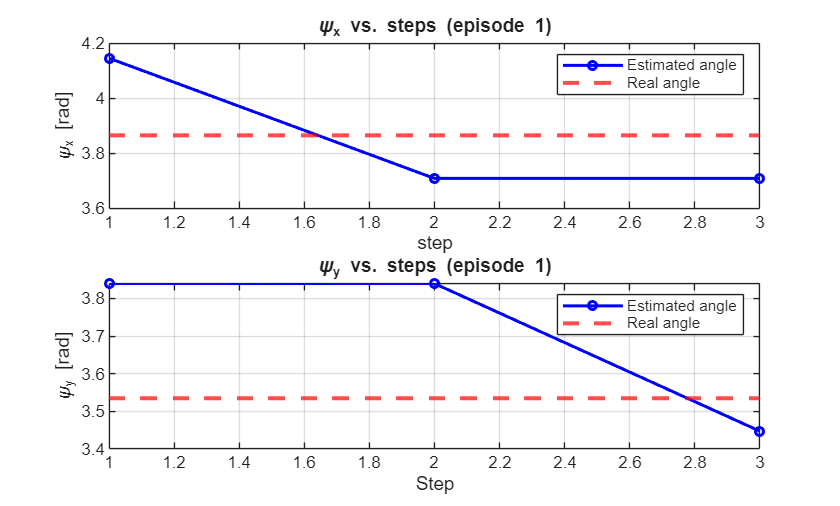

% Plots
figure
subplot(2,1,1);
plot(1:stepCount, psi_x_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4); hold on;
yline(psi_x_true, 'r--', 'LineWidth', 2);
title(['\psi_x vs. steps (episode ' num2str(episode) ')']);
xlabel('step'); ylabel('\psi_x [rad]'); legend('Estimated angle','Real angle'); grid on;

subplot(2,1,2);
plot(1:stepCount, psi_y_est_history, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4); hold on;
yline(psi_y_true, 'r--', 'LineWidth', 2);
title(['\psi_y vs. steps (episode ' num2str(episode) ')']);
xlabel('Step'); ylabel('\psi_y [rad]'); legend('Estimated angle','Real angle'); grid on;

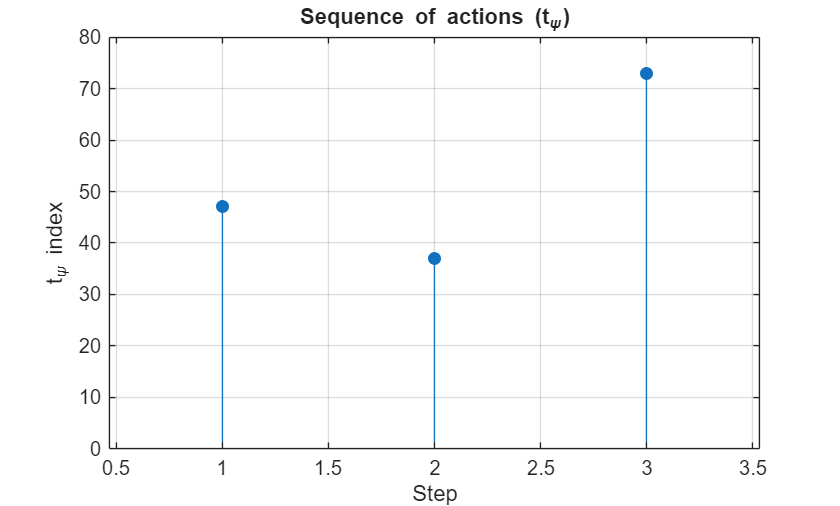


figure
stem(1:stepCount, actions, 'filled'); title('Sequence of actions (t_{\psi})');
xlabel('Step'); ylabel('t_{\psi} index'); grid on;


function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end


% Plot 2D-DFT
% figure                
% R_psi_x_y = fliplr(flipud(reshape(abs(r_psi_x_y_t{max_t_psi(i_N,i_t,i_itr),i_t}), [N_x(i_N), N_y(i_N)])))';
% %coordinates with the electric angle indexes k_x and k_y as defined in
% %the Parameters.mlx file
% % [X,Y] = meshgrid(linspace(1,N_x(i_N),N_x(i_N))+(max_t_psi_x(i_N,i_t,i_itr)-1)/T_x,linspace(1,N_y(i_N),N_y(i_N))+(max_t_psi_y(i_N,i_t,i_itr)-1)/T_y);
% % %coordinates with the electric angle
% [X,Y] = meshgrid(2*pi/N_x(i_N)*(linspace(1,N_x(i_N),N_x(i_N))+(max_t_psi_x(i_N,i_t,i_itr))/T_x),...
%     2*pi/N_y(i_N)*(linspace(1,N_y(i_N),N_y(i_N))+(max_t_psi_y(i_N,i_t,i_itr))/T_y));
% 
% contourf(X,Y,abs(R_psi_x_y));
% % contourf(abs(R_psi_x_y));
% colorbar
% grid on;
% xlabel('$\psi_\mathrm{x}$ [rad]','Interpreter','latex');
% ylabel('$\psi_\mathrm{y}$ [rad]','Interpreter','latex');
% %Tick angles
% X=2*pi/N_x(i_N)*(linspace(1,N_x(i_N),N_x(i_N))+(max_t_psi_x(i_N,i_t,i_itr)-1)/T_x);
% set(gca, 'XTick', X);
% X_Tick_text=cell(1,length(X));
% for j=1:length(X)
%     X_Tick_text{j}=strcat('$',num2str((X(j))/pi,2),'\pi$');
% end
% set(gca, 'XTickLabel', [X_Tick_text], 'TickLabelInterpreter', 'latex');
% 
% Y=2*pi/N_y(i_N)*(linspace(1,N_y(i_N),N_y(i_N))+(max_t_psi_y(i_N,i_t,i_itr))/T_y);
% set(gca, 'YTick', Y);
% Y_Tick_text=cell(1,length(Y));
% for j=1:length(Y)
%     Y_Tick_text{j}=strcat('$',num2str((Y(j))/pi,2),'\pi$');
% end
% set(gca, 'YTickLabel', [Y_Tick_text], 'TickLabelInterpreter', 'latex');
% % 
% % set(gca, 'YTick', [0:0.25:2]*pi);
% % set(gca, 'YTickLabel', [{"0","$0.25\pi$","$0.5\pi$","$0.75\pi$","\pi","$1.25\pi$","1.5\pi","$1.75\pi$","2\pi"}], 'TickLabelInterpreter', 'latex');
% % axis([0 2*pi 0 2*pi])
% set(gca,'FontSize',font,'GridColor','white');
% legend_text={strcat('SNR$=',num2str(SNR_dB,3),'$ dB,',' $N=$',num2str(N_x(i_N)),'$\times$',num2str(N_y(i_N)),', $T=$',num2str(T_x),'$\times$',num2str(T_y)),...
%     strcat('$\bar{\psi}_x=',num2str(psi_x(i_N,i_t,i_itr)/pi,2),'\pi$ rad, ',' $\hat{\psi}_x=',num2str(psi_x_est(i_N,i_t,i_itr)/pi,3),'\pi$ rad')...
%     strcat('$\bar{\psi}_y=',num2str(psi_y(i_N,i_t,i_itr)/pi,2),'\pi$ rad, ',' $\hat{\psi}_y=',num2str(psi_y_est(i_N,i_t,i_itr)/pi,3),'\pi$ rad')};
% % Get current axis limits
% x_limits = xlim;
% y_limits = ylim;
% % Define position (upper-right corner)
% x_pos = x_limits(2) - 0.89 * diff(x_limits); % Slightly inside the right edge
% y_pos = y_limits(1) + 0.85 * diff(y_limits); % Slightly inside the top edge
% text(x_pos,y_pos,legend_text,'Interpreter','latex','BackgroundColor','w','FontSize',font);
% set(gca,'FontSize',font);